# Opgave 1: Gram-Schmidt

% Oefening 3
m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0128    0.0233   -0.0172   -0.0160   -0.0094   -0.0082   -0.0124   -0.0131   -0.0128   -0.0126   -0.0127   -0.0128   -0.0127   -0.0127   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128   -0.0128
    0.0429    0.0245    0.0555    0.0517    0.0414    0.0417    0.0422    0.0425    0.0433    0.0430    0.0430    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0

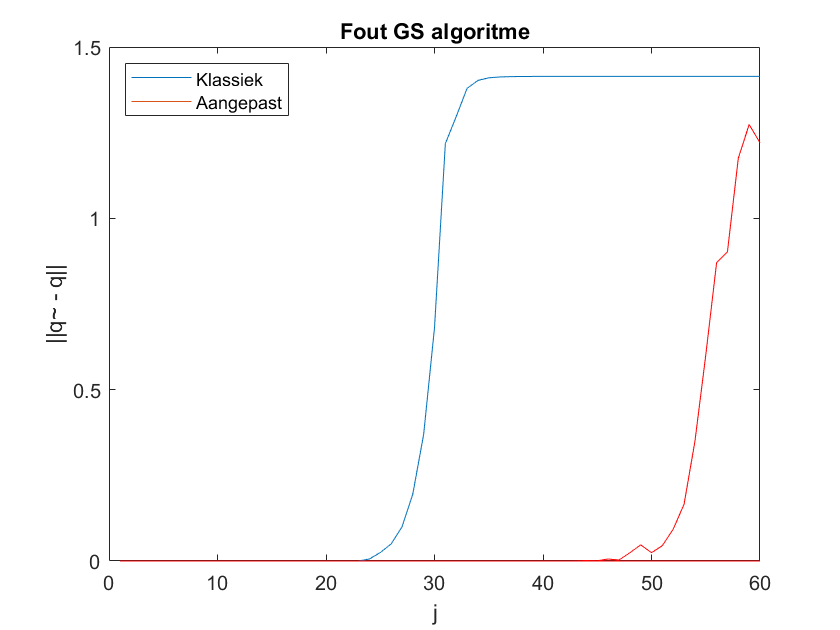


% Oefening 4
e1 = zeros(n);
e2 = zeros(n);

[Q1,~] = klGS(A);
[Q2,~] = modGS(A);

for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
    e2(j) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest') % fout is exponentieel ma geen idee waarom

% Oefening 5
m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0766   -0.0365   -0.0685
    0.0459    0.0394    0.0453
   -0.0938   -0.0777   -0.1014
    0.0730    0.1432    0.0661
    0.0059    0.0157    0.0234
   -0.0511   -0.1025   -0.0488
    0.0389    0.0095    0.0258
    0.0486    0.0244    0.0728
    0.0651    0.0764    0.0569
   -0.0081    0.0730   -0.0156


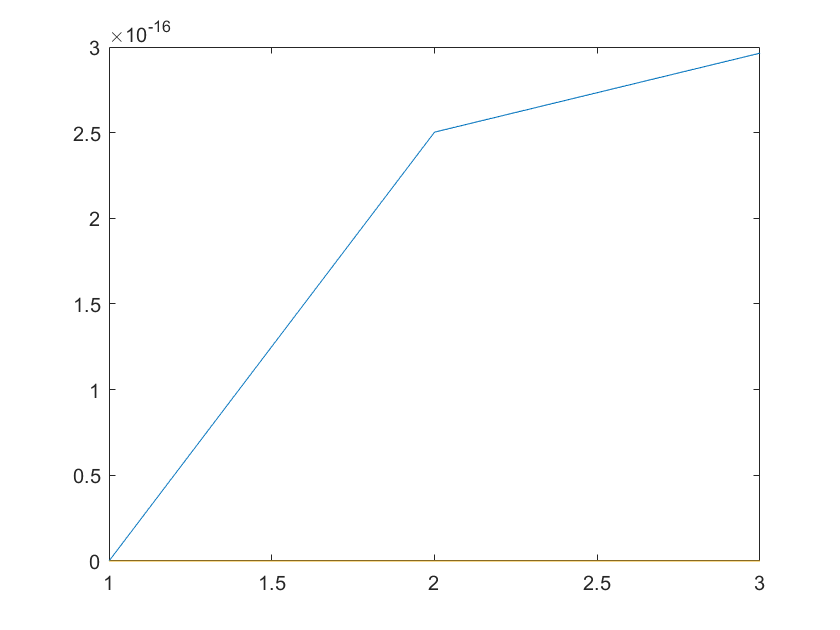


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

% Oefening 9
m = 200;
n = 50;
k = 1:50

k =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



B = randn(m,n);
[Q,~] = qr(B,0)

Q =    -0.0205   -0.1658    0.0161   -0.0636    0.0918    0.0571   -0.1803    0.0951    0.0140   -0.1371    0.0023    0.1207    0.0883   -0.0602    0.0986   -0.0322   -0.0852   -0.0531    0.0022    0.0797   -0.1199    0.1349   -0.0877    0.0039    0.0121   -0.0356    0.0350   -0.0284    0.1016   -0.0444   -0.0045    0.0836    0.0413   -0.0934    0.1023    0.1091   -0.0538   -0.1081    0.0504   -0.0269   -0.0313   -0.0502    0.0193    0.0025    0.0960    0.0594    0.0009   -0.0896    0.0869    0.0070
   -0.0441   -0.0191    0.0908    0.0067   -0.0658    0.0004    0.0168   -0.0948    0.0450   -0.1180   -0.0041   -0.0518   -0.0419    0.0029   -0.0311    0.0471    0.0417   -0.0338    0.0885   -0.0801    0.0479   -0.1760    0.0605    0.0025    0.0510   -0.0227    0.0233    0.1577   -0.0016   -0.0865   -0.0030    0.0590   -0.0499    0.0017   -0.0485    0.0386   -0.0205   -0.0317   -0.0177    0.0184    0.0384   -0.0396   -0.0836   -0.1179   -0.0619    0.0485   -0.0217   -0.0751   -0.0815   -0


V = randn(n) % change this to orthogonal matrix

V =     0.6136    1.0376    0.0998   -0.4436    0.9859    0.3522    1.4452    0.9001    1.6361    1.2833    1.0596    0.9993    0.0322   -1.8306    0.6871   -0.3644   -0.0693    0.2617   -1.1525   -1.5471    1.4734    1.5525   -1.5284   -0.5164   -1.8554    1.4586    0.4732    0.2089   -0.7360    0.7308    0.8041   -1.0878    0.0987   -0.6724   -0.6422   -0.3917   -1.1862   -1.1721   -0.5926    0.6637    0.8816    2.5038    0.3130   -0.1087   -0.4706   -1.0889   -0.3476   -0.7757    3.0441    1.2944
    1.2459    0.0769    2.1964    0.4371    0.2819    0.4590    0.6217    0.7929    1.3246    0.3605    1.8304   -1.5903    0.3973    1.7905    0.7474    0.1622   -0.2385    1.2838    0.9004    0.7324    1.2412   -0.3459    0.3450    1.4961   -1.6649   -0.1598   -2.4807   -1.7816   -2.0267    0.4052   -0.5740    0.8050    0.6176   -0.8694    0.0124    0.8674   -0.7167    0.5675   -0.3934    0.9035    1.6784   -0.2542    1.3603   -0.2426   -1.5645    2.7100    0.6031   -1.0299    2.7328   -0


D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D

D = D(:,:,1) =

    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0142         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   


A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A

A = A(:,:,1) =

   -0.3315   -0.9667    0.3800   -0.1687   -0.8218   -0.3078   -0.0570   -0.7642    1.6874   -1.6652   -0.6588    0.8770    0.1998    0.9521    0.1508    0.2057   -0.2914   -0.7660    0.1526   -0.2222   -0.9869   -1.4741   -0.0361   -0.0736    0.2943   -0.1881   -0.2541    0.3580    0.9877    0.2389    0.5707    0.4180    0.0657    0.0794   -1.2791    0.7663    0.6470   -0.7704   -0.6161   -0.2494   -1.3113   -1.7089   -0.1580    0.1183    0.9348   -0.1239   -0.3046   -0.0449    0.6346    0.2943
   -0.0199    0.7190   -0.2586    0.6484    0.1913    0.0507    0.7980    0.8003   -0.9443   -0.0920   -0.8402   -0.0480    0.0308   -0.6478   -0.4287    0.6827   -0.2027   -0.3673   -0.0539    0.5443    1.3971   -1.2274    0.0759    0.3250   -0.3003   -0.3076    0.5838   -0.0307   -0.4541    1.0040   -0.7348   -0.6037   -0.6480   -0.3851   -0.9776   -1.0830   -0.8206   -0.5547    0.1735    0.9903   -0.3111   -1.2848   -0.8217   -0.1513   -0.0664   -0.3225   -0.0193    0.7170   


K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 	1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



% Oefening 10
Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1

Q1 = Q1(:,:,1) =

   -0.0333   -0.1047    0.0491   -0.0307   -0.0740    0.0124    0.0128   -0.0480    0.1153   -0.1466   -0.0430    0.0446   -0.0210    0.1624    0.0094   -0.0183   -0.0226   -0.1155    0.0073   -0.0605   -0.0609   -0.1316   -0.0722   -0.1022    0.0867    0.0584   -0.0692    0.0518    0.0018    0.1232    0.1206    0.1083    0.0556    0.0738   -0.1442    0.0500    0.0255   -0.0213   -0.0083   -0.0789   -0.0611   -0.0153   -0.0428   -0.1208    0.1231    0.0826   -0.0823    0.0423   -0.0224    0.0973
   -0.0020    0.0713   -0.0374    0.0725    0.0152   -0.0206    0.0837    0.0356   -0.0618   -0.0248   -0.0895   -0.0025    0.0082   -0.0220    0.0146    0.1007   -0.0769   -0.0283   -0.0522    0.0963    0.1095   -0.0425    0.0649    0.0265    0.0446   -0.0969    0.0175   -0.0504    0.0064    0.0483   -0.0963   -0.0127    0.0238   -0.0122   -0.0791   -0.1610    0.0452   -0.0040   -0.0541    0.0557    0.0612   -0.1316   -0.1140   -0.0191   -0.0395   -0.0341    0.0627   -0.0976 


Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2

Q2 = Q2(:,:,1) =

   -0.0333   -0.1047    0.0491   -0.0307   -0.0740    0.0124    0.0128   -0.0480    0.1153   -0.1466   -0.0430    0.0446   -0.0210    0.1624    0.0094   -0.0183   -0.0226   -0.1155    0.0073   -0.0605   -0.0609   -0.1316   -0.0722   -0.1022    0.0867    0.0584   -0.0692    0.0518    0.0018    0.1232    0.1206    0.1083    0.0556    0.0738   -0.1442    0.0500    0.0255   -0.0213   -0.0083   -0.0789   -0.0611   -0.0153   -0.0428   -0.1208    0.1231    0.0826   -0.0823    0.0423   -0.0224    0.0973
   -0.0020    0.0713   -0.0374    0.0725    0.0152   -0.0206    0.0837    0.0356   -0.0618   -0.0248   -0.0895   -0.0025    0.0082   -0.0220    0.0146    0.1007   -0.0769   -0.0283   -0.0522    0.0963    0.1095   -0.0425    0.0649    0.0265    0.0446   -0.0969    0.0175   -0.0504    0.0064    0.0483   -0.0963   -0.0127    0.0238   -0.0122   -0.0791   -0.1610    0.0452   -0.0040   -0.0541    0.0557    0.0612   -0.1316   -0.1140   -0.0191   -0.0395   -0.0341    0.0627   -0.0976 


Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3

Q3 = Q3(:,:,1) =

   -0.0333   -0.1096    0.0473   -0.0504   -0.0540    0.0557    0.0621    0.0080    0.0342   -0.1358   -0.0944   -0.0437   -0.0497    0.0890   -0.0414    0.0414    0.0543   -0.1012   -0.0217   -0.0625   -0.0444   -0.1281   -0.1042    0.0058   -0.0061   -0.0412   -0.0636   -0.0645   -0.0447    0.0973    0.0829    0.0759   -0.0704   -0.0843   -0.1606   -0.0743    0.0906   -0.0821   -0.0774   -0.0681   -0.0927    0.0700    0.0649   -0.0813   -0.0684    0.0796   -0.0826   -0.0745   -0.0023    0.0833
   -0.0020    0.0688   -0.0392    0.0739    0.0042   -0.0453    0.0277    0.0052   -0.0236   -0.0021   -0.0471    0.0019   -0.0002   -0.0277    0.0055    0.0575   -0.0209   -0.0068   -0.0388    0.0674    0.0714   -0.0164    0.0169    0.0202    0.0039   -0.0696   -0.0171   -0.0100    0.0230    0.0075   -0.0098   -0.0281    0.0032   -0.0092   -0.0282   -0.0203    0.0023   -0.0221   -0.0010   -0.0063    0.0071   -0.0061   -0.0040   -0.0019   -0.0249   -0.0034   -0.0102   -0.0046 


orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i).'*Q1(:,:,i));
end
orth1

orth1 =     0.0000
    0.0001
    0.0001
    0.0008
    0.0010
    0.0036
    0.0068
    0.0321
    0.0850
    0.5378



orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i).'*Q2(:,:,i));
end
orth2

orth2 =     0.0114
    0.0121
    0.0197
    0.0356
    0.0447
    0.1003
    0.1370
    0.2414
    0.5494
    0.9871



orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i).'*Q3(:,:,i));
end
orth3

orth3 =    30.1099
   33.1402
   37.6734
   33.8948
   35.8674
   31.0869
   31.9737
   31.0799
   30.6106
   30.7556


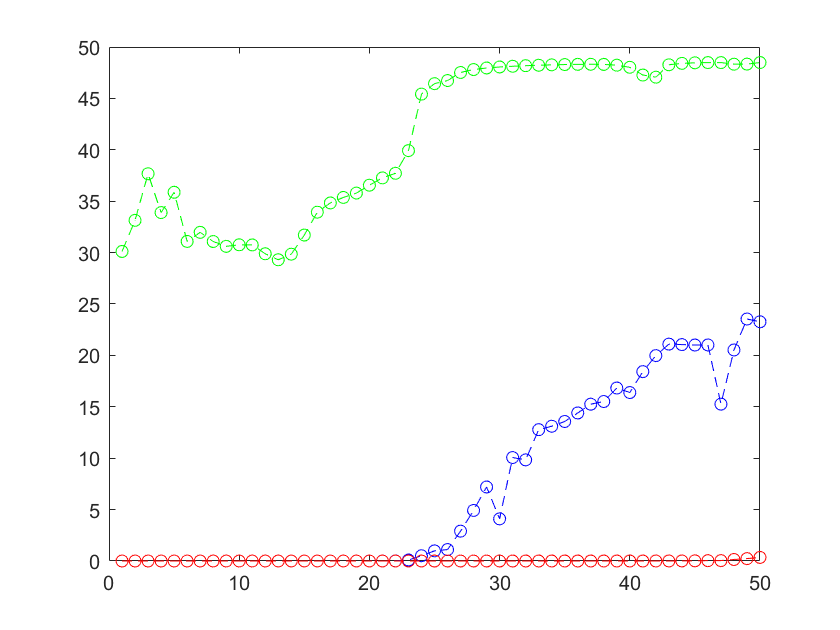


plot(k, orth1, 'b--o', k, orth2, 'r--o', k, orth3, 'g--o')


%Fout is veel te groot voor KLGS en herGS, kan niet!

# Opgave 2: Iteratieve methoden

A = sprand(1000,1000,10);
n = length(A);
m = 100;
v = rand(n,1);

[V,H] = Arnoldi(A,v,m);

Unrecognized function or variable 'Arnoldi'.